format long g
subset_spacing = ---;  % edit

calculated_strain = readtable("Strain Data.xlsx");
calculated_strain = table2array(calculated_strain);
real_strain = 1/(1+subset_spacing)*(calculated_strain);

force = readtable("Force Data.xlsx");
force = table2array(force);

area_mm = ---;   % edit
area_m = area_mm/1000000;

stressPa = force/area_m;
stressMPa = stressPa/1000000;

dydx = gradient(stressMPa(:)) ./ gradient(real_strain(:));
yy = smooth(dydx);
range_values = [];

for i = 1:length(yy)
    if (i+1 < length(yy)) && (abs(yy(i+1)-yy(i)) < 5000) && (yy(i) > 100000)
       range_values = [range_values i];
    end
end

y1 = min(range_values);
y2 = max(range_values);

UTS = max(stressMPa)

UTS =           890.635391504953



strain_at_failure = real_strain(end) * 100

strain_at_failure =           4.17175333271047



% stress_1 = 200;     % edit to manually define slope range
% stress_2 = 400;     % edit to manually define slope range
% [val1,y1]=min(abs(stressMPa-stress_1));
% [val2,y2]=min(abs(stressMPa-stress_2));
youngs_modulus = real_strain(y1:y2)\stressMPa(y1:y2)

youngs_modulus =             129639.6864656



offset_line = youngs_modulus*real_strain - youngs_modulus*0.002;
a = stressMPa - offset_line;
yeild_strength = interp1(a, stressMPa, 0)

yeild_strength =           689.930454187217



toughness = trapz(real_strain, stressMPa)

toughness =           32.3561774243018



for i = 1:length(yy)
        if (stressMPa(i) < yeild_strength + 3) && (stressMPa(i) > yeild_strength - 3)
           data_yeild_strength = stressMPa(i);
           limit = i;
        end
end
resilliance_strain = real_strain(1:limit);
resilliance_stress = stressMPa(1:limit);
resilliance = trapz(resilliance_strain, resilliance_stress)

resilliance =           3.06399814653101


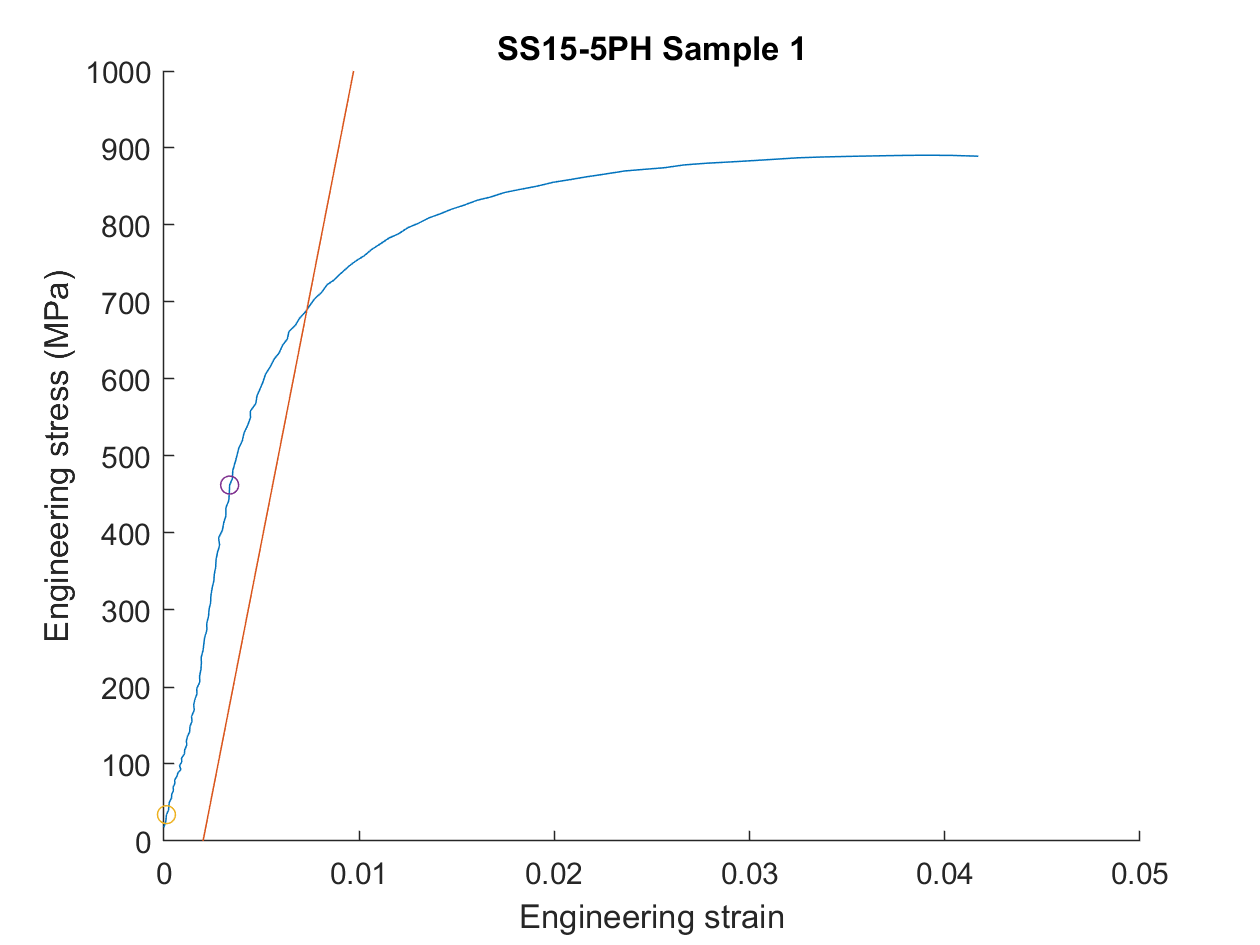

hold on
plot(real_strain, stressMPa)
plot(real_strain, offset_line)
scatter(real_strain(y1), stressMPa(min(range_values)))
scatter(real_strain(y2), stressMPa(max(range_values)))

title("---")  % edit
xlabel("Engineering strain")
ylabel("Engineering stress (MPa)")
xlim([0 .05])   % edit
ylim([0 1000])  % edit